# Topology Visualization

This demo is to show the backhaul network topologies used in the C++ simulation.

clear;
clc;
close all;

Random seed = 200, numRelays = 1152, all bss;

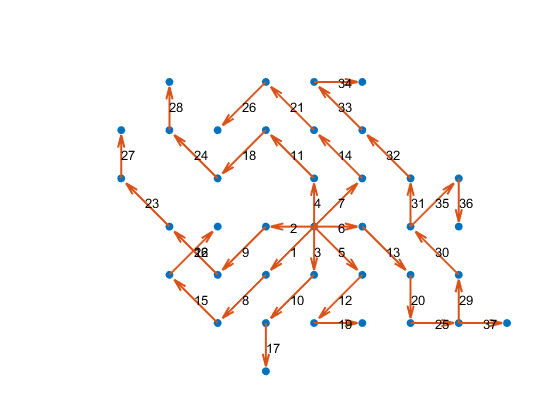

fileID = fopen('../../Data/Base_Stations_Grid/Data_BSInGrid_508_1152_200_5.txt');
C = textscan(fileID,'%f\t%f');
fclose(fileID);
bsGridIndex = cell2mat(C);
figure;
scatter(bsGridIndex(:,1), bsGridIndex(:,2),'filled');
hold on;
fileID = fopen('../../Data/Topology/Single_Mbs/Data_Topology_Tree_508_1152_38.txt');
C = textscan(fileID,'%f\t%f');
fclose(fileID);
bsLinks = cell2mat(C);
numRelays = 1152;
bsLinks = bsLinks - numRelays + 1;
pX = bsGridIndex(bsLinks(:,1),1);
pY = bsGridIndex(bsLinks(:,1),2);
vX = bsGridIndex(bsLinks(:,2),1) - bsGridIndex(bsLinks(:,1),1);
vY = bsGridIndex(bsLinks(:,2),2) - bsGridIndex(bsLinks(:,1),2);
quiver(pX,pY,vX,vY,'LineWidth',1.5,'MaxHeadSize',0.1);
for i = 1:length(bsLinks(:,1))
    txt = num2str(i);
    tX = (bsGridIndex(bsLinks(i,2),1) + bsGridIndex(bsLinks(i,1),1))/2;
    tY = (bsGridIndex(bsLinks(i,2),2) + bsGridIndex(bsLinks(i,1),2))/2;
    text(tX, tY, txt, 'FontSize', 10);
end
axis off;
daspect([1 1 1]);

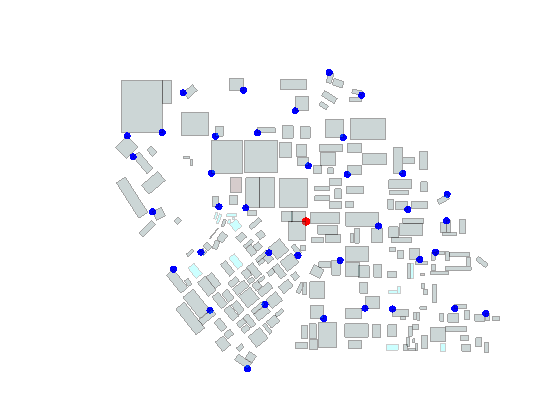

figure;
fileID = fopen('../../Data/Building_Vertices/Data_BuildingVertices.txt');
C = textscan(fileID,'%f,%f,%f');
fclose(fileID);
A = cell2mat(C);
numBuildings = length(A(:,1))/8;
% A B C D Ah Bh Ch Dh
% 1 2 3 4 5  6  7  8
for i=1:numBuildings
    patch('Vertices',A(8*(i-1)+1:8*i,:),'Faces',[1,2,3,4;1,2,6,5;2,3,7,6;3,4,8,7;4,1,5,8;5,6,7,8],...
        'FaceVertexCData',hsv(8),'FaceAlpha',0.2,'FaceColor','flat','EdgeAlpha',0.2,'FaceLighting','gouraud');
end
hold on
fileID = fopen('../../Data/Relays/Data_Relays_Surface_508_0.000100_1.txt');
C = textscan(fileID,'%f,%f,%f');
fclose(fileID);
A = cell2mat(C);
fileID = fopen('../../Data/Base_Stations/Data_BSSet_508_1152_200.000000_5.txt');
C = textscan(fileID,'%f,%f,%f');
fclose(fileID);
B = cell2mat(C);
A = [A;B];
for i = 1:length(bsLinks(:,1))
    src = A(bsLinks(i,1)+1152,:);
    dst = A(bsLinks(i,2)+1152,:);
    X = [src(1);dst(1)];
    Y = [src(2);dst(2)];
    Z = [src(3);dst(3)];
%     plot3(X,Y,Z,'LineWidth',1.5);hold on;
    if i == 1
        scatter3(src(1),src(2),src(3),40,'o','filled','MarkerFaceColor','r');
    end
    scatter3(dst(1),dst(2),dst(3),30,'o','filled','MarkerFaceColor','b');
end

view(2);
axis off;

## Plot paths

1) Read relays

fileID = fopen('../../Data/Relays/Data_Relays_Surface_508_0.000100_1.txt');
relays = fscanf(fileID,'%f,%f,%f',[3,Inf]);
numRelays = size(relays,2);
relays = relays';

2) Read BSs

fileID = fopen('../../Data/Base_Stations/Data_BSSet_508_1152_200.000000_5.txt');
BSs = fscanf(fileID,'%f,%f,%f',[3,Inf]);
numBSs = size(BSs,2);
BSs = BSs';

3) Read path hops

fileID = fopen('../../Data/Paths/Data_Results_508_1152_38_5_Sequence.txt');
hops = fscanf(fileID,'%d\t%d',[2,Inf]);
hops = hops(2,1:end-1);
numNodeHop = hops + 2;
numPaths = size(numNodeHop,2);

4) Read Paths

fileID = fopen('../../Data/Paths/Data_Results_508_1152_38_5_Paths.txt');
paths = fscanf(fileID,'%d');
assert(length(paths) == sum(numNodeHop));
pNodes = zeros(length(paths),3);
for i = 1:length(paths)
    if (paths(i) >= numRelays)
        pNodes(i,:) = BSs(paths(i)-numRelays+1,:);
    else
        pNodes(i,:) = relays(paths(i)+1,:);
    end
end

5) Plot paths

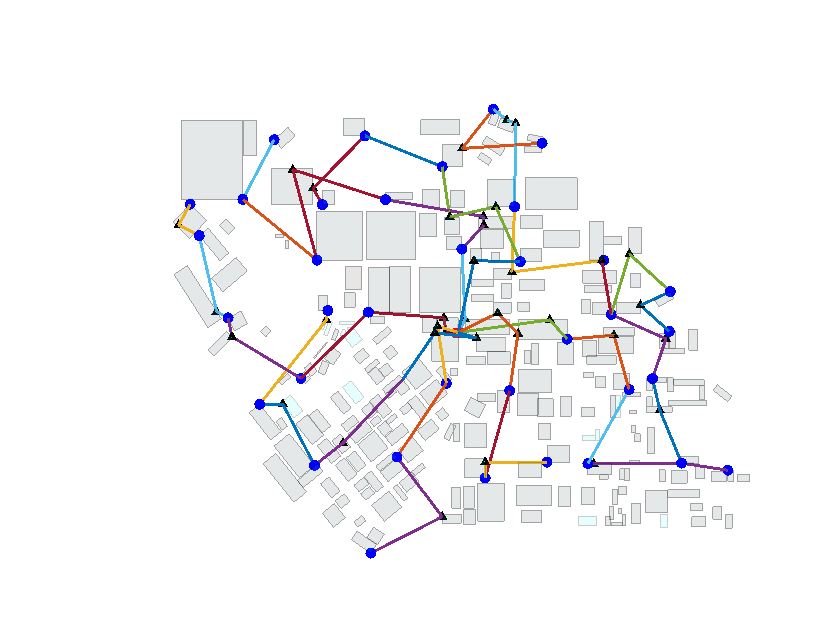

idx = 1;
for i = 1:numPaths
    n = numNodeHop(1,i);
    nodes = pNodes(idx:idx+n-1,:);
    plot3(nodes(:,1),nodes(:,2),nodes(:,3),'LineWidth',1.5); hold on;
    idx = idx + n;
    if i == 1
        scatter3(nodes(1,1),nodes(1,2),nodes(1,3),40,'s','filled','MarkerFaceColor','r');
    else
        scatter3(nodes(end,1),nodes(end,2),nodes(end,3),30,'o','filled','MarkerFaceColor','b');
    end
    if n > 2
        scatter3(nodes(2:end-1,1),nodes(2:end-1,2),nodes(2:end-1,3),20,'^','filled','MarkerFaceColor','k');
    end
    
end


% fileID = fopen('Results/pathpoints170221135247.txt');
% P = textscan(fileID,'%f,%f,%f');
% fclose(fileID);
% B = cell2mat(P);
% src = B(1,:);
% dst = B(end,:);
% for i = 1:length(B(:,1))
%     if(isequal(B(i,:),src))
%         idx1 = i;
%         j = idx1+1;
%         while(~isequal(B(j,:),dst))
%             j=j+1;
%         end
%         idx2 = j;
%         plot3(B(idx1:idx2,1),B(idx1:idx2,2),B(idx1:idx2,3),'LineWidth',1.5);hold on;
%         i = j+1;
%    end
% end